# Continuous Feedback System for Franka Emika Panda

Add Path

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")
addpath("..\ReadYAML\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q}\right) \ddot{\vec{q}} + C \left( \vec{q}, \dot{\vec{q}} \right) \dot{\vec{q}} + G \left( \vec{q} \right) = - K_{p} \left( \vec{q} - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Sampling Time, Time Step & Simulation Time

dt=config.dt;
SimulationTime=config.SimulationTime;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=config.TargetAngle';
StateInitial=config.StateInitial';

Gains

Kp=diag(config.Kp);
Kd=diag(config.Kd);

Time History Matrix

TorqueTimeHistoryContinuous=zeros(7, ...
    round(SimulationTime/dt)+1);

Solver Option

option=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

### Continuous Time Case

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,PDTorque(Kp,Kd,State,TargetAngle)),TimeSpan,StateInitial,option);
StateTimeHistoryContinuous=State';
for i=1:round(SimulationTime/dt)+1
    TorqueTimeHistoryContinuous(:,i)=PDTorque(Kp,Kd,StateTimeHistoryContinuous(:,i),TargetAngle);
end
toc

历时 3.830293 秒。


### Visualization for Continuous Time Control

Collect Data for Visualization

eTimeHistoryContinuous=StateTimeHistoryContinuous(1:7,:)-TargetAngle;

$e-t$ Diagram

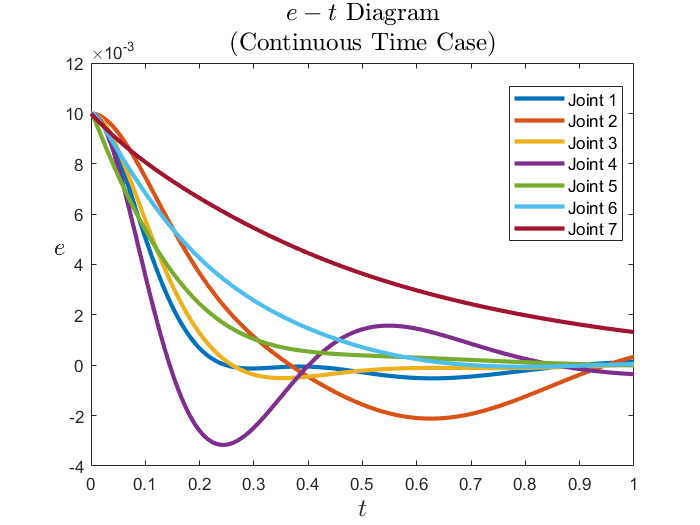

plot(TimeSpan,eTimeHistoryContinuous,"LineWidth",2.5)
title(["$$e-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

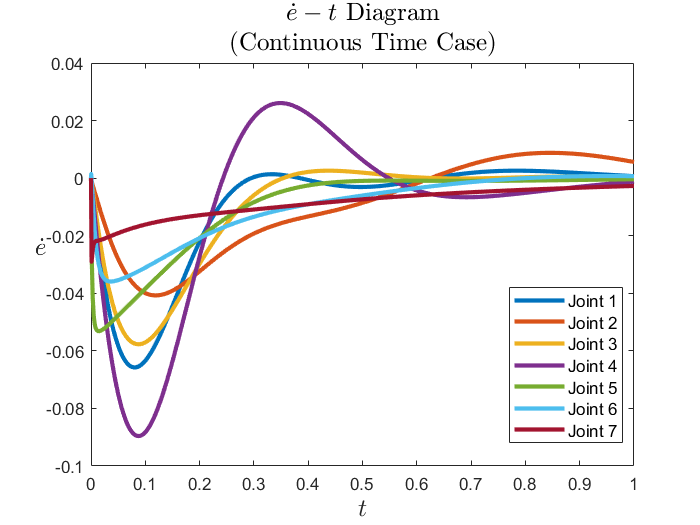

plot(TimeSpan,StateTimeHistoryContinuous(8:14,:),"LineWidth",2.5)
title(["$$\dot{e}-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\tau-t$ Diagram

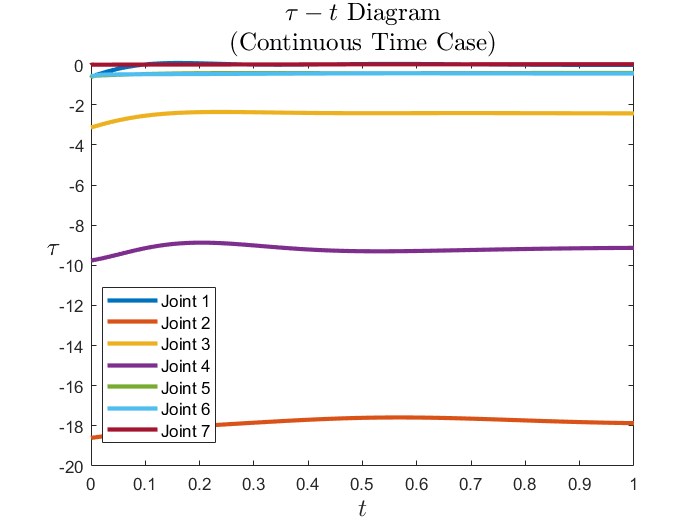

plot(TimeSpan,TorqueTimeHistoryContinuous,"LineWidth",2.5)
title(["$$\tau-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

## Visualization in Cartesian Space

MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocContinuous=panda.fkine(StateTimeHistoryContinuous(1:7,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

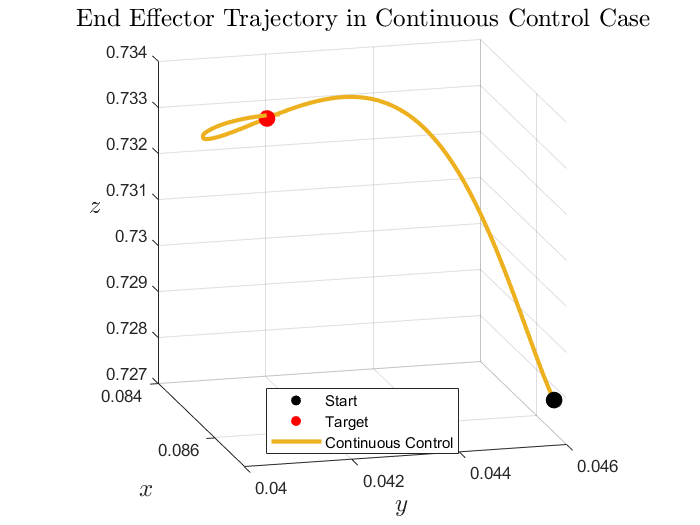

scatter3(EndEffectorLocContinuous(1,1),EndEffectorLocContinuous(2,1),EndEffectorLocContinuous(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"Red","filled","o")
plot3(EndEffectorLocContinuous(1,:),EndEffectorLocContinuous(2,:),EndEffectorLocContinuous(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory in Continuous Control Case", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Continuous Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

## Save Data

save("Data\StateTimeHistory_Continuous_"+ ...
    datestr(datetime("today"),"yyyy_mm_dd")+".mat","StateTimeHistoryContinuous")

Remove Path

rmpath("PandaDyn\")
rmpath("Dynamics\")
rmpath("..\ReadYAML\")